# Lecture 5: Forced Response

- Find the (undamped) eigenfrequencies $\omega$ and eigenmodes $\vec{u}$ of the system.

- Determine mass $\left\lbrack M_0 \right\rbrack$ and stiffness $\left\lbrack K_{0\;} \right\rbrack$matrices.

- Convert nominal coordinates $q$ to modal coordinates $\eta \;$ and vice-versa.

- Determine modal mass $\left\lbrack M^* \right\rbrack$ and modal stiffness $\left\lbrack K^* \right\rbrack$ matrices and modal force $N\left(t\right)$ 

- Simulate the response of the forced system.

Welcome! In this script we're going to analyze the motion of a forced 2DoF Spring Mass system with the equation of motion: 

$[M_0]{\vec{\ddot{q}}}+[K_0]\vec{q} = \vec{Q(t)}
$.

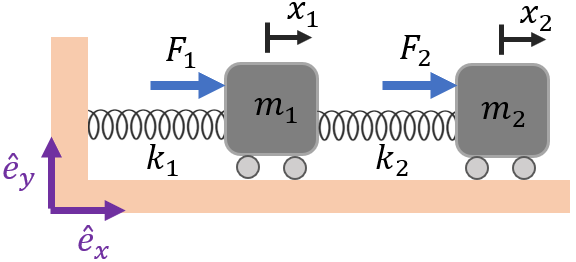

The generalized coordinates are chosen as$\vec{\;q} =\left\lbrack \begin{array}{c}
x_1 \\
x_2 
\end{array}\right\rbrack$.

The parameters of the model are:

- $m_1$ = 0.48               [kg]

- $m_2$ = 0.48               [kg]

- $k_1$ = 170                 [N/m]

- $k_2$ = 170                 [N/m]

- $F_1(t)$ = $50t$            [N]

- $F_2(t)$ = $20\sin \left(2\pi t\right)$ [N]

Using Lagranges Equation of Motion it can be shown that

$\left\lbrack M_0 \right\rbrack =\left\lbrack \begin{array}{cc}
m_1  & 0\\
0 & m_2 
\end{array}\right\rbrack$, $\left\lbrack K_0 \right\rbrack =\left\lbrack \begin{array}{cc}
k_1 +k_2  & -k_{2\;} \\
-k_2  & k_2 
\end{array}\right\rbrack$, $\vec{Q\left(t\right)} =\left\lbrack \begin{array}{c}
F_1 \left(t\right)\\
F_2 \left(t\right)
\end{array}\right\rbrack$

## Mass and Stiffness matrices

clc; clear all; close all;

% Parameter values:
m1 = 0.48;                             
m2 = 0.48;
k1 = 170;
k2 = 170;

% Mass and Stiffness matrices can be derived from Lagrange Equation and are given here:
M = [m1, 0;                     % kg (Mass Matrix)
    0, m2];
K = [k1+k2, -k2;                % N/m (Stiffness Matrix)
    -k2,    k2];

## Eigenmodes and eigenfrequencies

To find the (undamped) eigenfrequencies and eigenmodes we set all external forces and damping = 0. Then, we guess a solution in the form $\vec{q}(t) = \vec{u} \cos(\omega t+\phi)$.


$$[M_0]\ddot{q}+[K_0]q = 0
$$



$$-\omega ^2[M_0]\vec{u}\cos(\omega t+\phi)+ [K_0]\vec{u}\cos(\omega t+\phi) = 0$$



$$-\omega ^2 [M_0]\vec{u} + [K_0]\vec{u} = 0$$



$$\underbrace{\omega^2}_{\lambda} \vec{u} =\underbrace{ [M_0]^{-1}[K_0]}_{[A]}\vec{u}$$


This is in the form of the eigenvalue/eigenvector solution $\lambda \vec{u} = [A] \vec{u}$. So that means the eigenfrequencies and eigenmodes are found from `eig(A)`.

[U,lambda] = eig(M\K);         % Solve for eigenmatrix (U) and eigenvalues matrix (lambda)
u1 = U(:,1)                    % 1st eigenmode

u1 =    -0.5257
   -0.8507


u2 = U(:,2)                    % 2nd eigenmode

u2 =    -0.8507
    0.5257



w = sqrt(diag(lambda));        % Solve for eigenfrequencies (rad/s)
w1 = w(1)                      % 1st eigenfrequency

w1 = 11.6310

w2 = w(2)                      % 2nd eigenfrequency

w2 = 30.4503

Applying the principle of superposition to the two solutions: $ \vec{u_1} \cos(\omega_{1}t + \phi_1)$  and  $ \vec{u_2} \cos(\omega_{2}t + \phi_2)$ yields the following equation of motion for free vibration. $A_{1\;} ,A_2 ,\phi_1 ,\phi {\;}_{2\;}$are constants to be determined from initial conditions. 


$$\vec{q(t)} =A_1 \vec{u_1} \cos(\omega_{1}t + \phi_1) + A_2 \vec{u_2} \cos (\omega_{2}t + \phi_2)$$


## Modal mass and stiffness matrices

Solve the equation by assuming solution of the form $q=\left\lbrack U\right\rbrack \eta \;$and premultiplying by ${\left\lbrack U\right\rbrack }^{T\;}$. 


$$[M_0]\ddot{q}+[K_0]q = Q(t)
$$



$$[M_0][U]\ddot{\eta}+[K_0][U]\eta =Q(t)
$$



$$\underbrace{[U]^T[M_0][U]}_{[M^*]}\ddot{\eta}+\underbrace{[U]^T[K_0][U]}_{[K^*]}\eta = \underbrace{[U]^TQ(t)}_{N(t)}$$


M_star = transpose(U)*M*U          % Modal Mass (kg)

M_star =     0.4800         0
         0    0.4800


K_star = transpose(U)*K*U          % Modal Stiffness (N/m)

K_star =    64.9342    0.0000
   -0.0000  445.0658


## Forced Response

The modal mass and modal stiffness matrices will always be diagonal which means the EoMs are uncoupled:

$\left\lbrack \begin{array}{cc}
m_1^*  & 0\\
0 & m_2^* 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\ddot{\eta_1 } \\
\ddot{\eta_2 } 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
k_1^*  & 0\\
0 & k_2^* 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\eta_1 \\
\eta_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
N_1 \left(t\right)\\
N_{2\;} \left(t\right)
\end{array}\right\rbrack$.

This yields a set of indepent equations:

$m_1^*$$\ddot{\eta_1 }$+$k_1^*$$\eta_1 =$$N_1 \left(t\right)$

$m_2^*$$\ddot{\eta_2 }$+$k_2^*$$\eta_2 =$$N_2 \left(t\right)$

These uncoupled equations can be solved for analytically or numerically to find $\eta$. Then apply $q=\left\lbrack U\right\rbrack \eta \;$to obtain the original degrees of freedom again.

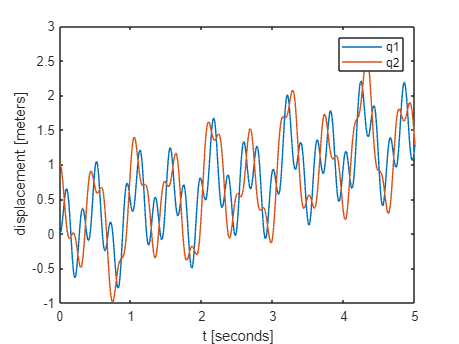

% Simulation details beyond scope for this course %
q0 = [0;1];                     % Initial Conditions (position in original DoFs)
dq0 = [0;0];                    % Initial Conditions (velocity in original DoFs) 
eta0 = inv(U)*q0;               % Initial Conditions (position in modal coordinates)
deta0 = inv(U)*dq0;             % Initial Conditions (velocity in modal coordinates)
y0 = [eta0;deta0];

[t,y] = ode45(@(t,y) odefun(t,y,U,M_star,K_star),[0,5],y0);

eta_1 = y(:,1);                 % Solution for eta
eta_2 = y(:,2);

q = U*[eta_1, eta_2]';          % Solution for q

plot(t,q(1,:))
hold on
plot(t,q(2,:))
xlabel('t [seconds]')
ylabel('displacement [meters]')
legend('q1','q2')

function dydt = odefun(t,y,U,M_star,K_star)
    %ODE 45 solves dy/dt = f(t,y) = Ay+B(t)

    F1 = 50*t;
    F2 = 20*sin(2*pi*t);
    Q = [F1; F2];  
    N = transpose(U)*Q;
    A = [zeros(2),eye(2); -inv(M_star)*K_star, zeros(2)];
    B = [zeros(2,1); inv(M_star)*N];
    
    dydt = A*y+B;
end